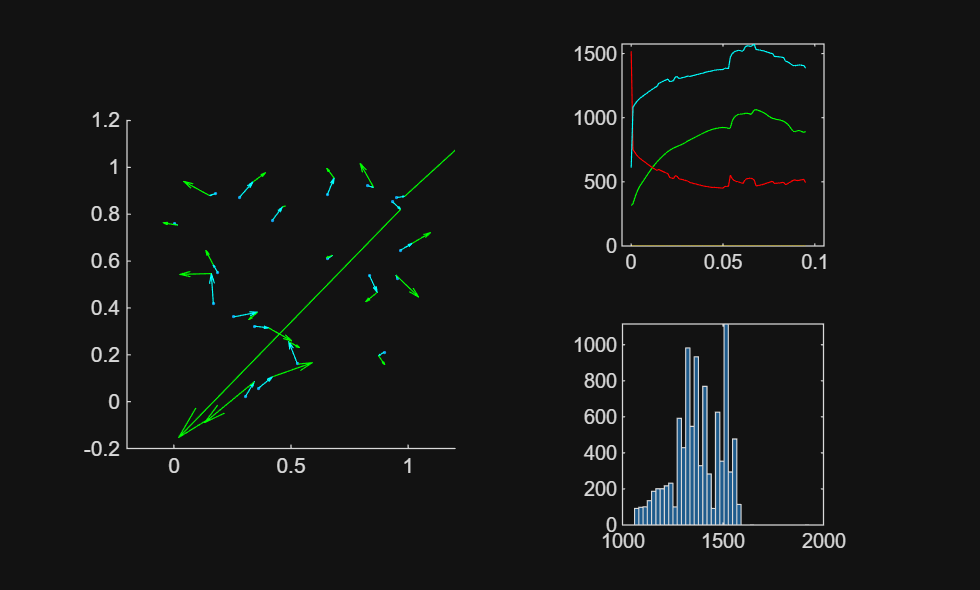


Xdim = 1;
Ydim = 1;
Ndim = 20;
Tdim = 100;
IGDim = 100;
R = .01;
WFC = 1;
dt = .00001;
K=1;
BD = .2;
g = 100;
FW = .1;
PrxD = clip(Xdim*rand(1,Ndim),R,Xdim-R);
PryD = clip(.5*Ydim*rand(1,Ndim),R,Ydim-R);
PvxD = 5*rand(1,Ndim);
PvyD = 5*rand(1,Ndim);

Prx = gpuArray(PrxD);
Pry = gpuArray(PryD);
Pvx = gpuArray(PvxD);
Pvy = gpuArray(PvyD);

% Prx = (PrxD);
% Pry = (PryD);
% Pvx = (PvxD);
% Pvy = (PvyD);

subplot(2,2,[1 3])
P1 = scatter(PrxD,PryD,2^9,[.07 .6 .9],"filled");
hold on;

currentunits = get(gca,'Units');
set(gca, 'Units', 'Points');
axpos = get(gca,'Position');
set(gca, 'Units', currentunits);
markerWidth = R/diff(xlim)*axpos(3); % Calculate Marker width in points
set(P1, 'SizeData', markerWidth^2)
Q1 = quiver(PrxD,PryD,PvxD,PvyD,'off','cyan');
Q2 = quiver(PrxD,PryD,PvxD*0,PvyD*0,'off','g');
axis equal
xlim([-BD Xdim+BD])
ylim([-BD Ydim+BD])
subplot(2,2,2)
E1 = plot([0],[sum(Pvx.^2+Pvy.^2)],'g');
xlim([-.05 1.05]*dt*IGDim*Tdim)
hold on
axis square;
E2 = plot([0],[K*sum(sum(((ones(1,Ndim).*Prx'-ones(Ndim,1).*Prx).^2+(ones(1,Ndim).*Pry'-ones(Ndim,1).*Pry).^2).^(-.5).*(1-eye(Ndim)),"omitmissing"),"omitmissing")],'r');
E3 = plot([0],[0]);%2*g*sum(Pry)
E4 = plot([0],.333*[get(E1,"YData")+get(E2,"YData")+get(E3,"YData")],'cyan');
subplot(2,2,4)
Ethb = gpuArray([.90 1.05]*(get(E1,"YData")+get(E2,"YData")+get(E3,"YData")));
H1 = histogram(gather(Ethb),40);
axis square;
set(H1, 'BinLimitsMode', 'auto');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for t=1:Tdim

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



for IG=1:IGDim

% Prx = mod(Prx,Xdim);
% Pry = mod(Pry,Xdim);


dx = abs(ones(1,Ndim).*Prx'-ones(Ndim,1).*Prx);
dy = abs(ones(1,Ndim).*Pry'-ones(Ndim,1).*Pry);
% BIC = 1./(vecnorm(cat(3,min(dx,(Xdim-dx)),min(dy,(Ydim-dy))),2,3)-eye(Ndim));
BIC = 1./(vecnorm(cat(3,dx,dy),2,3));

Fx = sum((ones(1,Ndim).*Prx'-ones(Ndim,1).*Prx).*BIC.^3,1,"omitmissing");
Fy = sum((ones(1,Ndim).*Pry'-ones(Ndim,1).*Pry).*BIC.^3,1,"omitmissing");
Pvx = Pvx - dt*K.*Fx;
Pvy = Pvy - dt*K.*Fy;

Prx = mod(Prx,Xdim);
Pry = mod(Pry,Xdim);

Prx = Prx + dt * Pvx;
Pry = Pry + dt * Pvy; 

Kt = sum(Pvx.^2+Pvy.^2);
U1t = .5*K*sum(sum(BIC.*(1-eye(Ndim)),"omitmissing"),"omitmissing");
% U2t = 2*g*sum(Pry);
U2t = 0;
Et = (Kt+U1t+U2t);
Ethb = [Ethb Et];

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

PrxD = gather(Prx);
PryD = gather(Pry);
PvxD = gather(Pvx);
PvyD = gather(Pvy);
% EthbD = gather(Ethb);

% PrxD = (Prx);
% PryD = (Pry);
% PvxD = (Pvx);
% PvyD = (Pvy);

Tt = dt*IGDim*t;

set(P1, 'XData', (PrxD), 'YData', (PryD));
set(Q1, 'XData', (PrxD), 'YData', (PryD),'Vdata',10*IGDim*dt*PvyD,'Udata',10*IGDim*dt*PvxD);
set(Q2, 'XData', 10*IGDim*dt*PvxD+(PrxD), 'YData', 10*IGDim*dt*PvyD+(PryD),'Udata',IGDim*dt*gather(Fx),'Vdata',-IGDim*dt*gather(Fy));
PlotNXY(E1,gather(Kt ),Tt);
PlotNXY(E2,gather(U1t),Tt);
PlotNXY(E3,gather(U2t),Tt);
PlotNXY(E4,gather(Et ),Tt);
set(H1,'Data',gather(Ethb));

[~,BinEdges] = histcounts(gather(Ethb),H1.NumBins);
H1.BinEdges= BinEdges;
H1.BinLimits= [min(BinEdges),max(BinEdges)];
drawnow
end

function PlotNXY(P,Y,X)
set(P, 'YData', [get(P,'Ydata') Y]);
set(P, 'XData', [get(P,'Xdata') X]);
end